# Worksheet 4, Part 1 / 4: Beyond Stocks

*Author: *Zachary del Rosario, Fall 2022

*Important Note:* Worksheet 4 comes to you in **four parts**; `worksheet4_part1.mlx`, `worksheet4_part2.mlx`, `worksheet4_part3.mlx`, and `worksheet4_part4.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- How to use **vectors** and **matrices** to represent population infection data.

- How to use **matrices** to represent sets of equations & social connectivity.

- How to use **vectorized** operations to operate on large batches of data.

- Integrate these ideas to run and interpret an **agent-based model**.

### Additional Files

Make sure to download these additional files from Canvas and place them in the same folder as this worksheet:

- `infected.csv`

- `simulate_absir.m`

clear;

## State: Unraveling the Stock Abstraction with Agent-based Models

So far, we have worked with *compartmental models*; that is, models that do not consider individual things (infected individuals, meme-loving students, individual bikes), but rather **abstract** individual things into collections we call **stocks**. For example, the following is the state of a 6-person SIR compartmental model.

% State of the SIR compartmental model
S = 5; % Susceptible individuals
I = 1; % Infected individuals
R = 0; % Recovered individuals

Note that this state does not tell us *who* is infected, only *how many* people are infected.

We've seen a number of ways that we can use compartmental / stock-and-flow models to answer interesting modeling questions. However, there are many questions we might like to ask that this compartmental model cannot help answer:

- Will I become infected by this disease?

- Will organizing society into pods help slow the spread?

- Do international travel bans work to prevent the spread of disease *after* cases have been identified from international travel?

### **Exercise 1 / 11**

### 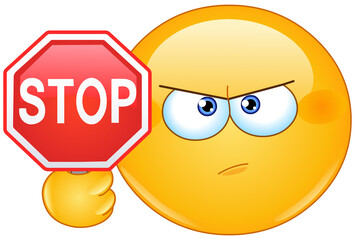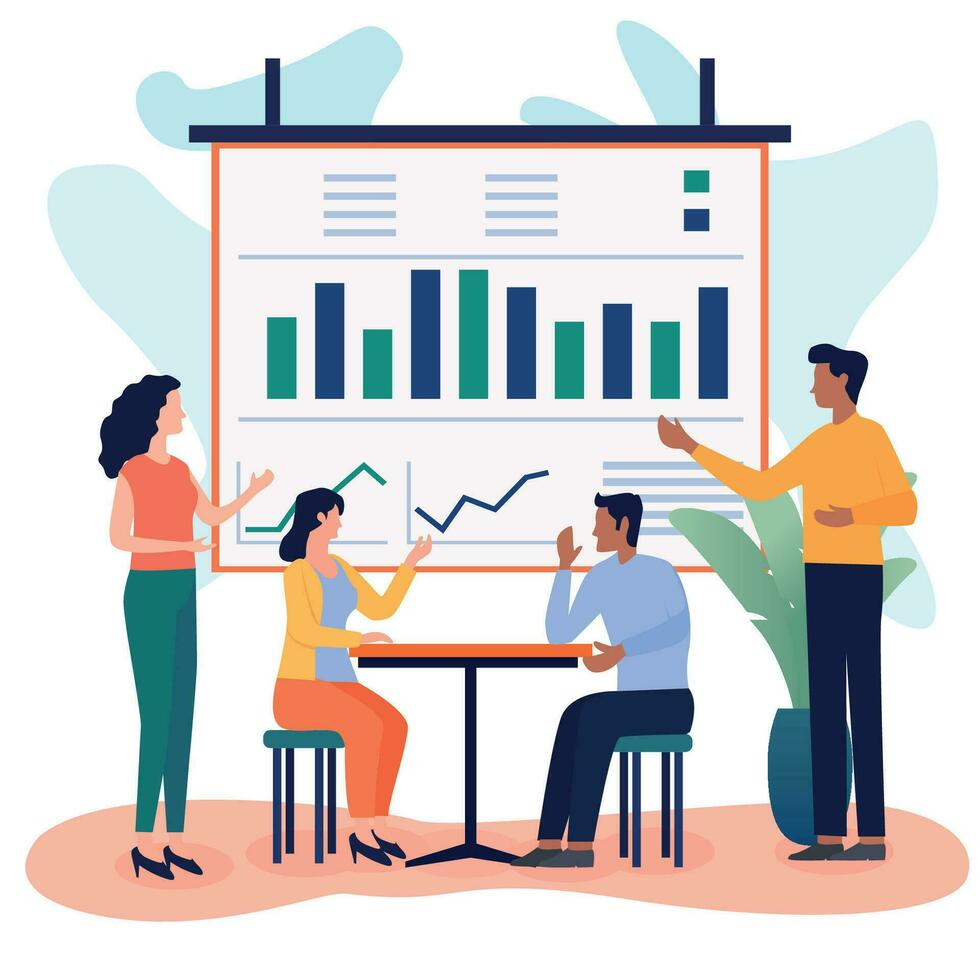

**STOP & DISCUSS:** For each of the modeling questions noted above, discuss with your table why the compartmental SIR model cannot help answer that question, and jot down notes from your discussion below:

- What is my chance of being infected, relative to everyone else in the population?

- *    (Your ****table's**** discussion here)*

It doesn't take individual health issues into account.

- Will organizing society into pods help slow the spread more than masking?

- *    (Your ****table's ****answer here)*

Only looks at the population as a whole, assuming everyone is interacting with each other.

- Do international travel bans work to prevent the spread of disease *after* cases have been identified from international travel?

- *    (Your ****table's**** answer here)*

Doesn't track individual cases/multiple things per person. Question is too specific.

To answer these sorts of modeling questions, we will need to go beyond stocks! Rather than simply counting the number of people who are Susceptible, Infected, or Recovered, we will need to track whether each *individual* person is S, I, or R. To do this, we will make use of **vectors** to represent the state of a set of individuals. For instance, for a population of 6 persons, we might have the following state:

% State of SIR *agent-based* model
Sv = [0; 1; 1; 1; 1; 1];
Iv = [1; 0; 0; 0; 0; 0];
Rv = zeros(6, 1);

These are **binary** **vectors** because they only contain binary values (0 or 1).

This state indicates that Individual 1 is infected, the remaining individuals (2 through 6) are susceptible, and no individuals have recovered yet. Tracking state in this way would allow us to address many new modeling questions!

### Exercise 2 / 11

Modify the following code to represent a population of infected persons where only Individual 3 is infected.

Iv = zeros(6, 1) % Initial population

Iv =      0
     0
     0
     0
     0
     0



% TODO: Modify Iv so that individual #3 is infected
% (write your code here)
Sv = [0; 1; 1; 1; 1; 1];
Iv = [0; 0; 1; 0; 0; 0];
Rv = zeros(6, 1);
% Do not edit these lines;
% use to check your work
assert(all(Iv(1:6 ~= 3) == 0), 'An individual other than 3 is infected')
assert(Iv(3) == 1, 'Individual 3 is not infected')
disp('Assertions passed!')

Assertions passed!


Since this model tracks the state of individuals (sometimes called "agents"), this is called an **agent-based model**.

### Exercise 3 / 11

Modify the following infected state `Iv` to represent the case where Individuals 4, 5, and 6 are infected.

Iv = zeros(6, 1); % Initial population

% TODO: Modify Iv so that the last three individuals are infected
% (write your code here)
Sv = [0; 1; 1; 1; 1; 1];
Iv = [0; 0; 0; 1; 1; 1];
Rv = zeros(6, 1);
% Do not edit these lines;
% use to check your work
assert(all(Iv(1:3) == 0), 'None of the first three individuals should be infected')
assert(all(Iv(4:6) == 1), 'All of the last three individuals should be infected')
disp('Assertions passed!')

Assertions passed!


### Exercise 4 / 11 (Fix It!)

In your own words, describe what is different about the agent-based SIR model, as compared with the compartmental SIR model.

- *(Write your answer here) *A compartmental SIR model has each of its stocks equal to a whole number, while agent-based stocks are vectors. 

How does using an agent-based SIR model change the kinds of modeling questions we can pose, as compared with the compartmental model?

- *(Write your answer here) *We can track how likely specific people are to become infected based on their individual traits.

**STOP & DISCUSS:**

Turn to someone else at your table, chose one of the above questions, and copy down their response to the question you chose:

*(Who did you work with?)*

Ashley

*(Write your partner's response here.)*

The agent-based SIR model is different than the compartmental SIR model in that the agent-based SIR model can also track individuals and their statuses.

Do you agree with their answer? 

(Write your answer here)

Yes

Then move on to the following steps: Apply the ideas of "clear and concise writing" to *improve* this answer. Remember that these include:

- Cut the fluff

- Use active voice

- Use simple vocabulary

*(**Modify** your partner's description here.)*

Unlike the compartmental SIR model, the agent-based SIR model can track individuals and their statuses.

Now compare your partner's modifications with your original statement. How did they improve your writing?

(Write your response here)

They cut the fluff/more simple vocabulary.

## Tracking State History with a Matrix

Since the state of the model is defined in terms of vectors, we need to use matrices to represent the history of the state.

### Exercise 5 / 11

Plot the infection data `I` inside the dataset `tab_infected`. 

❗ Make sure to label your axes!!! ❗

*Hint:* Run `help table` if you need help remembering how to work with table datasets.

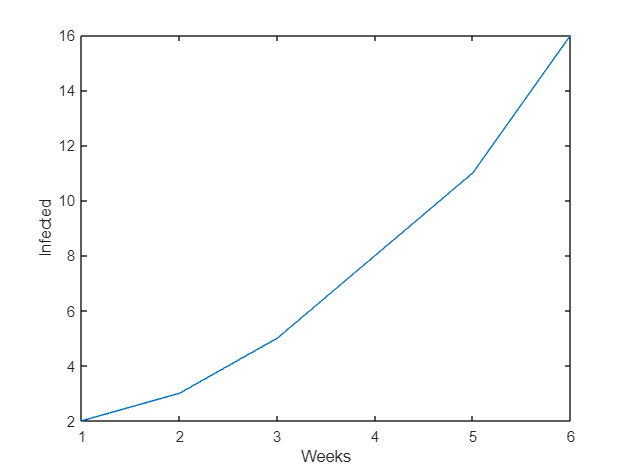

% The following code loads infected data from Worksheet2 into a table
tab_infected = readtable('infected.csv');

figure(); clf;
% TODO: Visualize the infection data here
plot(tab_infected,"W","I")
xlabel("Weeks")
ylabel("Infected")

However, with an agent-based model, the state is much more complicated. Since our state is defined by a vector, we must use a **matrix** to represent the time-history of the state. The following code shows an example time history of the Infected state with three timesteps.

% An example infection history
Ih = [
% t=1  2  3  % Timestep
    1, 1, 1; % Individual 1: Infected from the beginning
    0, 1, 0; % Individual 2: Infected at t=2 then recovered at t=3
    0, 0, 1; % Individual 3: Infected at t=3
    0, 0, 0; % Individual 4: Avoided infection
    0, 0, 1; % Individual 5: Infected at t=3
    0, 0, 0  % Individual 6: Avoided infection
]

Ih =      1     1     1
     0     1     0
     0     0     1
     0     0     0
     0     0     1
     0     0     0


The infection history matrix $I_h$ is is a collection of infection state vectors at different timesteps $I_t$; you can think of this a sequence of the infection state vectors going from $t=1$ to $t = T$.


$$I_h = [I_1, I_2, I_3, \dots, I_T]$$


How do we visualize a matrix? That's what the next exercise is about!

### Exercise 6 / 10

Visualize the infection history matrix `Ih` with the `spy()` command. Describe (in your own words) how the matrix is represented visually.

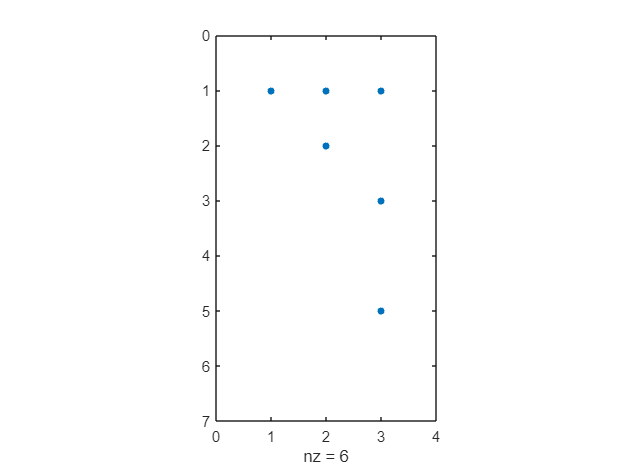

% TODO: Visualize Ih with the spy() command
spy(Ih)

- How is the matrix represented visually by the `spy()` command? What represents a "1"? What represents a "0"?

- *    (Write your response here)*

- A blue dot represents a 1 while if there's nothing it represents a 0.

- What do 0/1 correspond to, with respect to each individual's state?

- *    (Write your response here)*

- A 0 means that a person is not in that stock, while a 1 means they are in that stock.

- What can you tell about the infection history of the 6 individuals, based on this plot?

- *    (Write your response here)*

- You can tell when they got infected and how long they were infected for.

### Exercise 7/11

Read through the following section and run the code. Afterwards, for each line of code marked write a comment at the end of the line explaining what the code does.

Now that we have a way to represent and record the State of the system, we need to define an Action that advances the simulation in time. A simple way to do this would be to write a set of `if` statements:

% Define the current state of an individual
susceptible = 1;                    
infected = 0;                       
recovered = 0;                      

% What action does this individual encounter?
infection_exposure = 1;             
recovery_chance = 0;                

% Perform the Action to update the State
if infected == 0                    % WHAT DOES THIS LINE DO?
    if infection_exposure == 1      % WHAT DOES THIS LINE DO?
        susceptible = 0;            % WHAT DOES THIS LINE DO?
        infected = 1;               % WHAT DOES THIS LINE DO?
    end
end

% Print the state of the single individual
susceptible

susceptible = 0

infected

infected = 1

recovered

recovered = 0

However, this approach would require us to run the same set of actions in a `for` loop:

% Set the initial state of the model
Sv = [0; 1; 1];
Iv = [1; 0; 0];
Rv = zeros(3, 1);

% Define the actions to take
v_infect = [1; 1; 0];


for i = 1:3                         % WHAT DOES THIS LINE DO?
    if Iv(i) == 0                   % WHAT DOES THIS LINE DO?
        if v_infect(i) == 1         % WHAT DOES THIS LINE DO?
            Sv(i) = 0;              % WHAT DOES THIS LINE DO?
            Iv(i) = 1;              % WHAT DOES THIS LINE DO?
        end
    end
end

Sv

Sv =      0
     0
     1


Iv

Iv =      1
     1
     0


While an approach like this would work, it would end up being very computationally inefficient. Instead, we'll continue to think in terms of vectors and perform *vectorized operations*.

### Vectorized Operations

A *vectorized operation* is an operation that works on an entire vector. Simple operations like addition work on single values (scalars), but addition also adds entire vectors:

% Simple scalar addition
1 + 1

ans = 2

% Vectorized addition
[1, 2, 3] + [1, 0, 0]

ans =      2     2     3


Vectorized operations are important for a number of reasons. First, they allow us to write more computationally efficient code (try searching for the term "vector processor" online!). Second, they help us write simpler code. Learning how to think in terms of vectors and matrices will help us write overall better simulation codes.

### Exercise 8 / 11

Convert the for loop below into code that uses vectorized operations.

**Important note:** You need to write this code without using a `for` loop!

% Initialize vectors to add
v1 = [1 2 3 4 5 6 7 8 9];
v2 = [9 8 7 6 5 4 3 2 1];

% for loop approach
v_for = zeros(1, 9);
for i = 1:length(v1)
    v_for(i) = v1(i) + v2(i);
end

% TODO: Add v1 and v2 using vectorized operations
v_vec = v1+v2; % Replace this with the correct single line of code

**STOP & DISCUSS: Review your code implementation with the person next to you. **

Did you approach the problem in the same way? How did each of you get around not using a for loop?

(Discuss any differences or similarities here)

Yes, we added the vectors together.

Numerous operations in Matlab are vectorized, including logical (boolean) operators. These operators are like computational versions of English words such as "and," "or," or "not."  This logic helps us check if something is TRUE or FALSE. MATLAB accepts the inputs True and False, but they are more often represented with 1s and 0s

% A logical 1 represents True
3 == 3 % returns 1 - True

ans = logical
   1



% A logical 0 represents False
3 == 4 % returns 0 - False

ans = logical
   0


% Logical "and" &
0 & 0

ans = logical
   0


0 & 1; % returns 0
1 & 0; % returns 0
1 & 1; % returns 1

% Logical "or" |
0 | 0; % returns 0
0 | 1; % returns 1
1 | 0; % returns 1
1 | 1; % returns 1

% Logical "not" ~
~0; % returns 1
~1; % returns 0

You can also use parenthesis to control the order of operations of logical operations. Note that the "not" operation `~` will "invert" operations; for instance:

% NOT (one OR zero)...
~(1 | 0)

ans = logical
   0


% ... is the same as NOT one AND NOT zero
~1 & ~0

ans = logical
   0


Let's use these logical operations to implement the Action of the model.

To update the Infected state of the model, we make the following (reasonable) assumption:

- An individual is infected if they were already infected or if they are exposed to an infection risk and not already recovered.

Note the logical operations in this statement:

- An individual is infected if: (they were already infected **OR** they are exposed to an infection risk **AND** **NOT** already recovered).

Remember that these English words have symbolic equivalents in Matlab:

% OR  -> |
% AND -> &
% NOT -> ~

We can translate this natural language into computer code to help implement our model. To do this, we will introduce an infection exposure vector `v_infect` to list out all the individuals exposed to an infection. For instance, if Individual 1 (of 6 total) is exposed to infection, then we have

v_infect = [1; 0; 0; 0; 0; 0]

v_infect =      1
     0
     0
     0
     0
     0


### Exercise 9 / 11

Implement the infection Action described above using logical operators.

❗ **Important note:** You need to write this code without using a `for` loop! ❗

*Note:* You might be tempted to write the code `Iv = [1 0 1 0 0 0]`. However, while this will pass the `assert()` statements below, it is incorrect! You must use `Iv, Rv, `and` v_infect` to compute the new value of `Iv`.

% Initialize a population of six
Iv = zeros(6, 1);
% Individual 3 is infected to start
Iv(3) = 1;

% Suppose Individuals 1 and 6 are exposed to an infected individual
v_infect = [1; 0; 0; 0; 0; 1];

% However, Individual 6 is already recovered
Rv = [0; 0; 0; 0; 0; 1];

% TODO: Implement the action in code *WITHOUT* using a for loop
Iv = Iv+v_infect

Iv =      1
     0
     1
     0
     0
     1


Iv = Iv - Rv

Iv =      1
     0
     1
     0
     0
     0


% Modify this code to update the state

% NOTE: Do not edit these lines; 
% use this to check your work
assert(Iv(1) == 1, 'Individual 1 should be infected')
assert(Iv(3) == 1, 'Individual 3 should still be infected; do not simply override the vector Iv_new = v_infect')
assert(Iv(6) == 0, 'Individual 6 is recovered and cannot be infected; the code Iv_new = Iv | v_infect is wrong')
disp('Assertions passed!')

Assertions passed!


**STOP & DISCUSS: Review your code implementation with the person next to you. **

Did you approach the problem in the same way? How did each of you get around not using a for loop?

(Discuss any differences or similarities here) No, they used an or statement while I just did simple addition and subtraction.

We can go through the same process to define the Recovery Action:

- An individual is recovered (and no longer infected) if they are already recovered or if they are infected and manage to recover.

Like before, we introduce a recovery vector `v_recover` to list out all individuals who would potentially recover in a single timestep.

### Exercise 10 / 11

Implement the recovery action using logical operators.

*Hint 1:* You will need to update `Rv`, then `Iv`.

*Hint 2:* You should not use `v_infect` to update `Iv` in this step. Instead, you should use your updated value of `Rv` to update `Iv`.

% Suppose the following recovery pattern
v_recover = [0; 1; 1; 0; 0; 0];

% TODO: Modify Rv and Iv to implement the recovery action
Rv = Rv | (Iv & v_recover)

Rv = 6×1 logical array
   0
   0
   1
   0
   0
   1


Iv = ~Rv & Iv

Iv = 6×1 logical array
   1
   0
   0
   0
   0
   0




% NOTE: Do not edit these lines; 
% use this to check your work
assert(Iv(1) == 1, 'Individual 1 should be infected')
assert(~Iv(2)&~Rv(2), 'Individual 2 should be susceptible (neither infected nor recovered)')
assert(all(Iv(2:end) == 0), 'All individuals other than 1 should not be infected')
assert(Rv(3) == 1, 'Individual 3 should be recovered')
assert(Rv(6) == 1, 'Individual 6 should be recovered')
disp('Assertions passed!')

Assertions passed!


What rule should we use to update the state of the Susceptible vector? We can actually compute `Sv` directly from `Iv` and `Rv`.

Sv = ~Iv & ~Rv

### Exercise 11 / 11

Construct the susceptible state vector based on the infected `Iv` and recovered `Rv` vectors.

*Hint:* Remember that every individual can be in one *and only one* state. This means that, across `Sv`, `Iv`, or `Rv`, only one can have a `1` at the same vector index.

% TODO: Compute Sv from Iv and Rv
Sv = ones(6, 1); % Fix this code!
Sv = ~Iv & ~Rv

Sv = 6×1 logical array
   0
   1
   0
   1
   1
   0



% NOTE: Do not edit these lines; 
% use this to check your work
assert(Sv(1) == 0, 'Individual 1 should not be susceptible')
assert(Sv(2) == 1, 'Individual 2 should be susceptible')
assert(Sv(3) == 0, 'Individual 3 should not be susceptible')
assert(Sv(4) == 1, 'Individual 4 should be susceptible')
assert(Sv(5) == 1, 'Individual 5 should be susceptible')
assert(Sv(6) == 0, 'Individual 6 should not be susceptible')
disp('Assertions passed!')

Assertions passed!


## Looking Forward

We talked about enriching our description of state to consider individual persons. To do this, we had to talk about state as a vector. Next time, we'll discuss how to implement the action of our model with this more complex state. To do this, we'll have to talk more about matrices.

**Image Sources:**

Stop Sign: Adobe Stock

People Collaborating: [https://www.vecteezy.com/vector-art/27013850-business-meeting-vector-cartoon-illustration-in-a-flat-style-of-a-group-of-diverse-people-leading-a-discussion-at-a-table-near-a-whiteboard-with-charts-and-graphs-isolated-on-background](https://www.vecteezy.com/vector-art/27013850-business-meeting-vector-cartoon-illustration-in-a-flat-style-of-a-group-of-diverse-people-leading-a-discussion-at-a-table-near-a-whiteboard-with-charts-and-graphs-isolated-on-background)